clear all;
s0_add_paths;

# Create the image features

nOri = 8; nExample = 5;
orientations = linspace(0, pi, nOri+1);
orientations = orientations(1:end-1);

numpix  = 400;
fovs    = 12.5 * [1, 3/2, 1, 1]; % deg (the second data set had a larger field of view than the others)
fov     = fovs(1);
pixperdeg = numpix / fov;
ppc     = round(pixperdeg./0.75); % pixels per cycle
supp    = 6;

num     = round(ppc * supp); % number of pixels in 2 cycles
picMask = gen_disk(num, num*3/4, .95);
cenMask = gen_disk(num, num*3/4, .6);

[x, y]  = meshgrid((0:num - 1)/ppc);

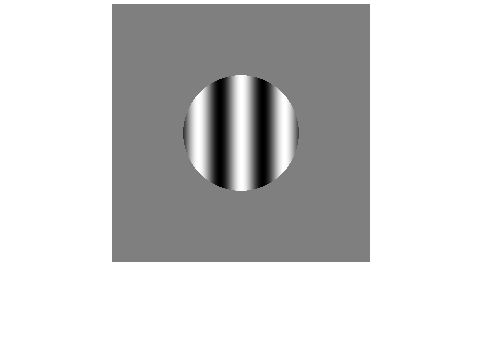

% get the center feature
i = 1;
theta = orientations(i);
wave_c = cos(theta);
wave_s = sin(theta);
h = exp(1i*(wave_c*x+wave_s*y)*pi*2);
I_center = cenMask.*real(h);
figure();
imshow(I_center, []);

### The stimuli with surround suprresion

Images vary across 8 orientations and 5 phase

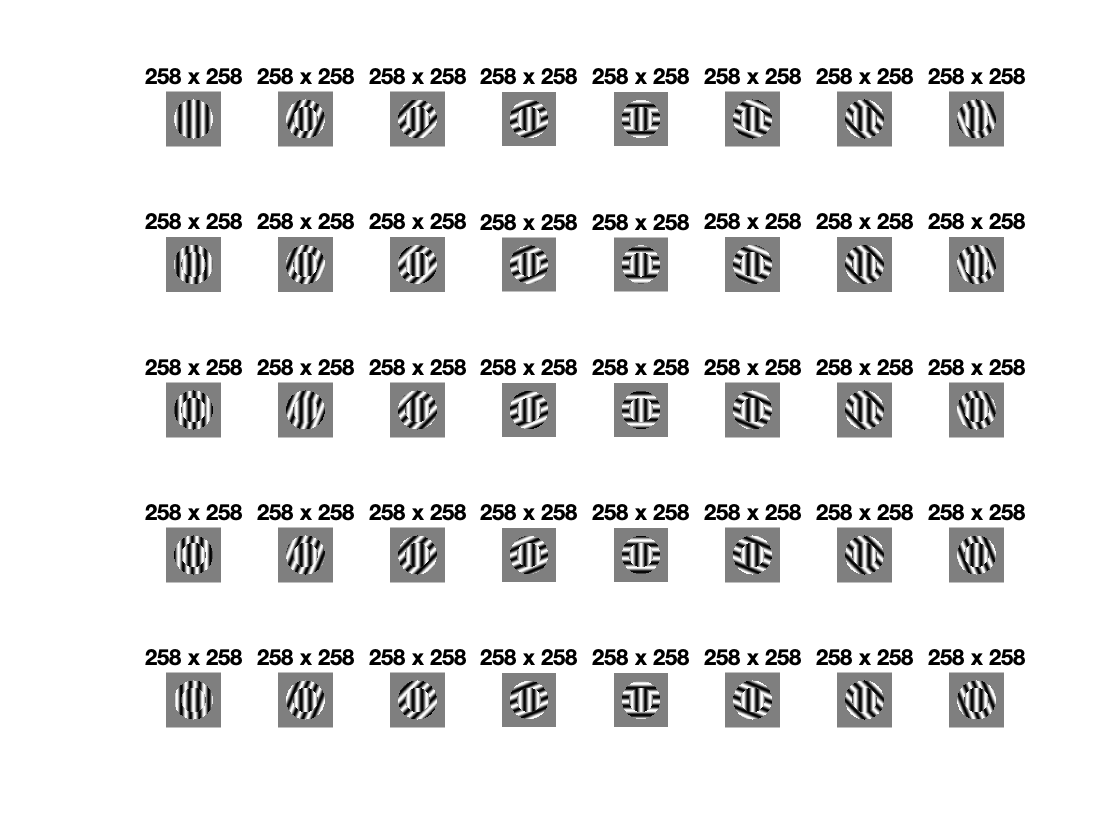

surr_stim = cell(nOri, nExample);
shift_step = round(ppc / (nExample));
for i = 1:nOri
    for j = 1:nExample
        shift = (j-1) * shift_step;
        [x, y]  = meshgrid((shift:num+shift- 1)/ppc);
        theta = orientations(i);
        wave_c = cos(theta);
        wave_s = sin(theta);
        h = exp(1i*(wave_c*x+wave_s*y)*pi*2);
        h = real(h);
        surr = .5*(picMask.*h.*(1-cenMask));
        surr_stim{i, j} = surr + .5*I_center;
    end
end
figure();
for i = 1:nOri
    for j = 1:nExample
        subplot(5, 8, (j-1)*8+i)
        imshow(surr_stim{i, j}, [])
        n = size(surr_stim{i, j}, 1);
        title(sprintf('%d x %d', n, n))
    end
end

## Stimuli used to create tuning curve

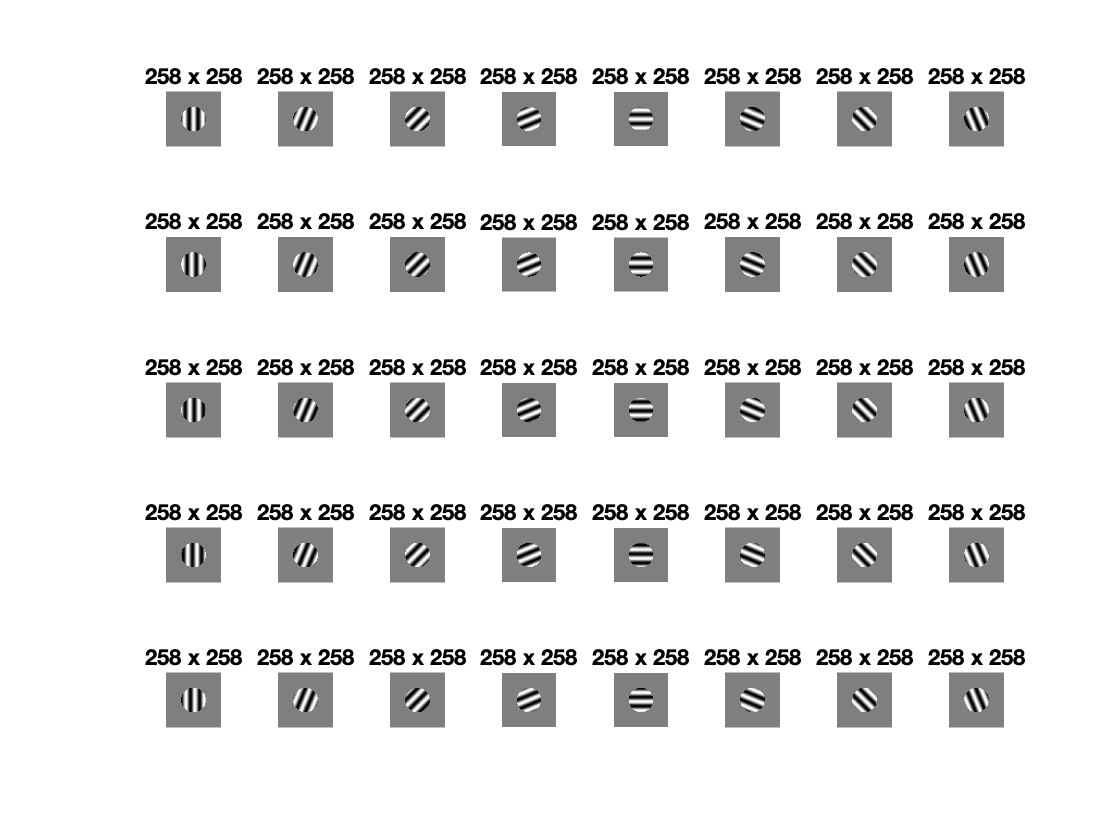

tune_stim = cell(nOri, nExample);
shift_step = round(ppc / (nExample));
for i = 1:nOri
    for j = 1:nExample
        shift = (j-1) * shift_step;
        [x, y]  = meshgrid((shift:num+shift- 1)/ppc);
        theta = orientations(i);
        wave_c = cos(theta);
        wave_s = sin(theta);
        h = exp(1i*(wave_c*x+wave_s*y)*pi*2);
        tune_stim{i, j} = .5*(cenMask.*real(h));
    end
end

figure;
for i = 1:nOri
    for j = 1:nExample
        subplot(5, 8, (j-1)*8+i)
        imshow(tune_stim{i, j}, [])
        n = size(tune_stim{i, j}, 1);
        title(sprintf('%d x %d', n, n))
    end
end

# Frame the problem

### Energy extraction

#### 
$$E(x,y,\theta) = \sum_{\phi}\left(I(x, y)F(x,y,\theta, \phi)\right)^2$$


#### * $I$ the image

#### * $F$ the filter (the neuron)

#### * $x,\;y$ indicates the neuron's location

#### * $x^{\prime } ,y^{\prime } \;$is the neuron's receptive field

#### * $\theta \;$ neuron's preferred orientation

#### * $\phi \;$ the phases, sine or cosine

### Get the filters (Neurons)

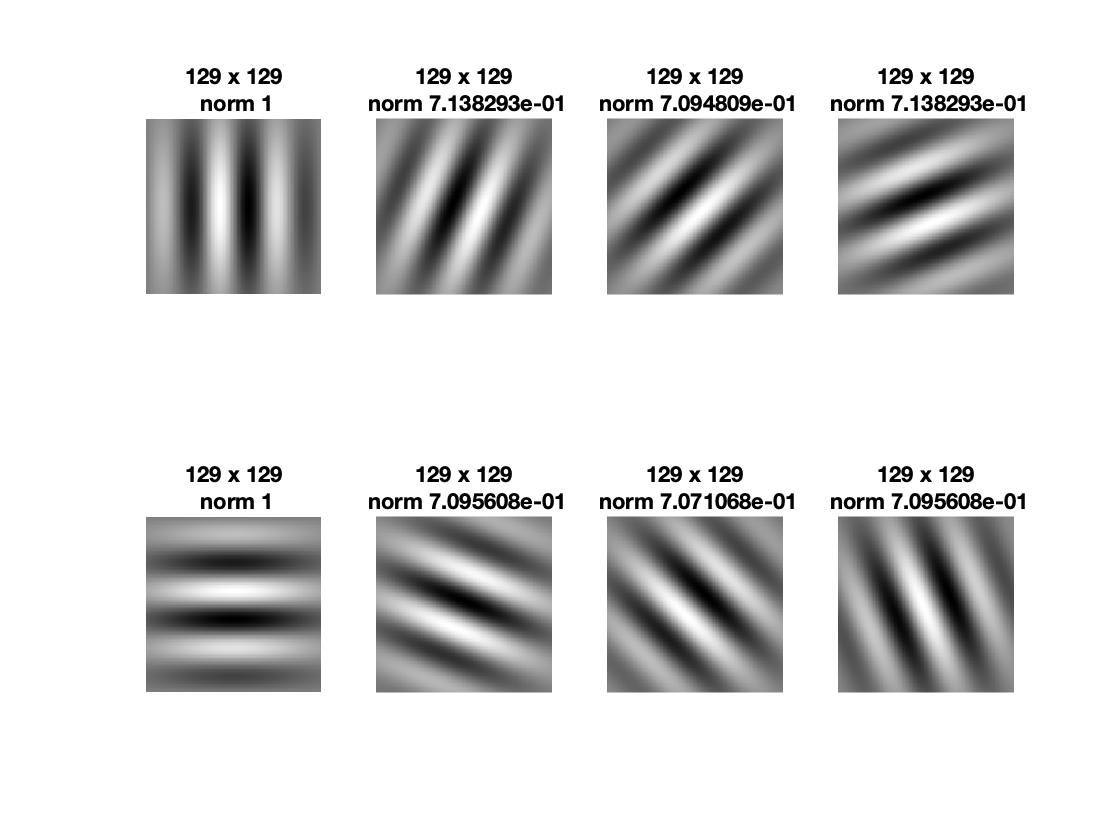

% extract contrast energy
% create filters
supp=3;
figure;
[Gabor_c, Gabor_s] = makeGaborFilter(ppc, orientations, supp);
for i = 1:nOri
    subplot(2, 4, i)
    imshow(Gabor_c{i}, [])
    n = size(Gabor_c{i}, 1);
    title(sprintf('%d x %d\n norm %d', n, n, norm(Gabor_c{i})))
end

### Extract the contrast energy 

% x, y, self_ori, stim_idx
surr_E = nan([size(I_center), nOri, nExample, nOri]);
tune_E = nan([size(I_center), nOri, nExample, nOri]);

for i = 1:nOri
    for j = 1:nExample
        tune_E(:, :, :, j, i) = Icontrast(tune_stim{i, j}, Gabor_c, Gabor_s);
        surr_E(:, :, :, j, i) = Icontrast(surr_stim{i, j}, Gabor_c, Gabor_s);
    end
end

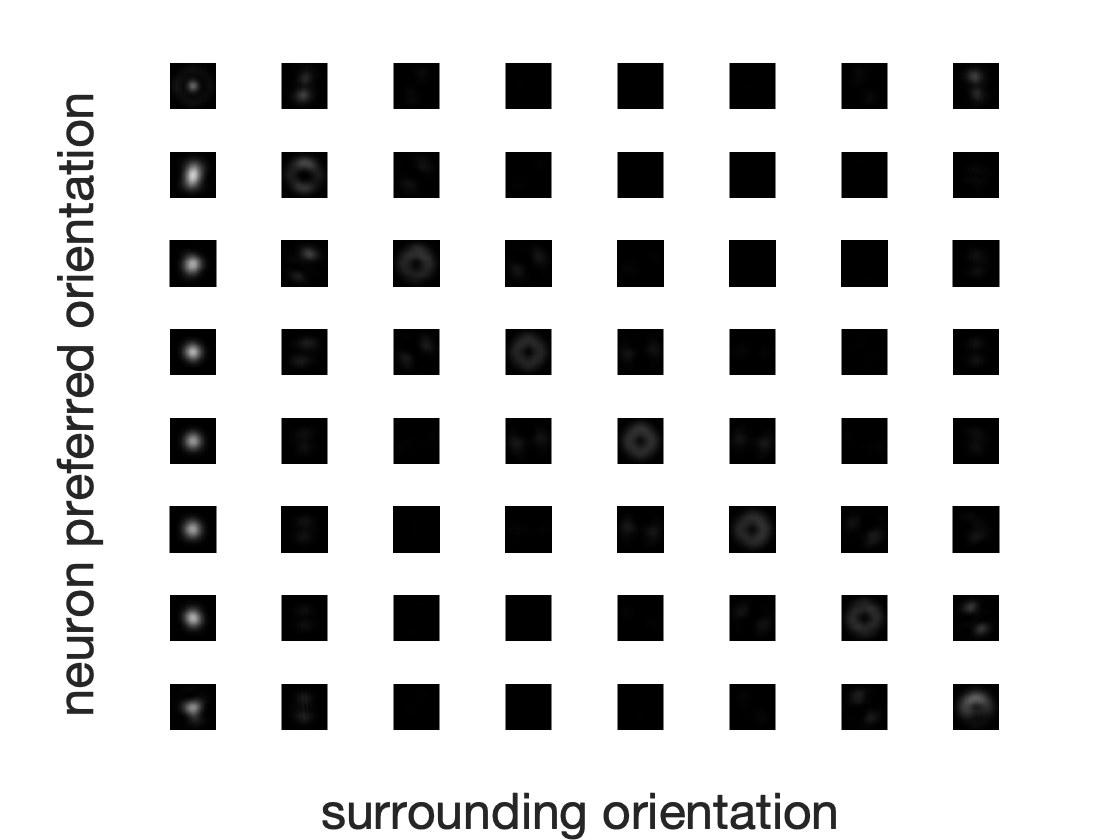

fig = figure;
surr_E1 = surr_E(:, :, :, :, :);
maxe = max(surr_E1(:));
mine = min(surr_E1(:));
for j = 1:nOri
    for i = 1:nOri
        subplot(nOri, nOri, nOri*(j-1)+i)
        tar = surr_E(:,:,i, 3, j);
        imshow(tar, [mine, maxe])
        meane = mean(tar(:));
        %title(sprintf('mean E: \n%d', meane))
    end
end

han=axes(fig,'visible','off');
han.XLabel.Visible='on';
han.YLabel.Visible='on';
ylabel(han,'neuron preferred orientation','FontSize', 25);
xlabel(han,'surrounding orientation','FontSize', 25);

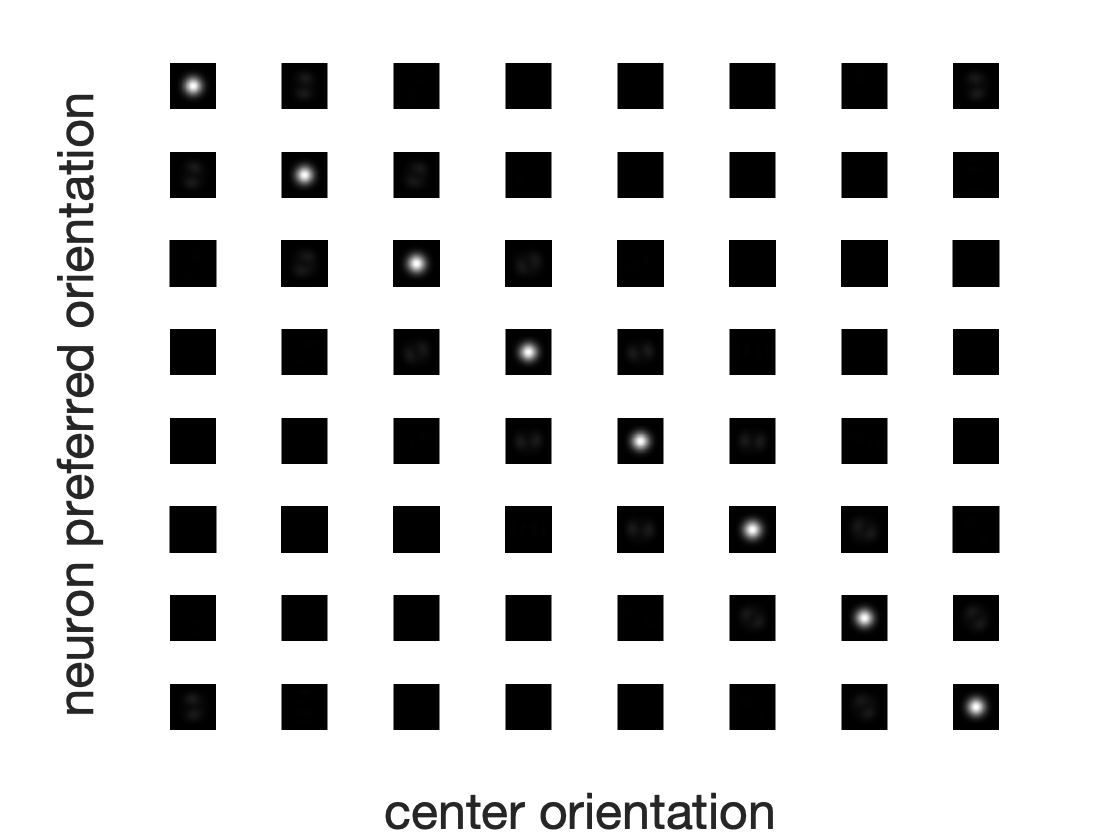

fig = figure;
tune_E1 = tune_E(:, :, :, :, :);
maxe = max(tune_E1(:));
mine = min(tune_E1(:));
for j = 1:nOri
    for i = 1:nOri
        subplot(nOri, nOri, nOri*(j-1)+i)
        tar = tune_E(:,:,i, 3, j);
        imshow(tar, [mine, maxe])
        meane = mean(tar(:));
        %title(sprintf('mean E: \n%d', meane))
    end
end

han=axes(fig,'visible','off');
han.XLabel.Visible='on';
han.YLabel.Visible='on';
ylabel(han,'neuron preferred orientation','FontSize', 25);
xlabel(han,'center orientation','FontSize', 25);

# Calculate the neurons' respone at the center 

### The general equation that calculate the response is 

#### 
$$d(\theta^c) = \sum_{x,y\in C} \frac{E(x, y, \theta^c)}{\sigma + Z(x,y,\theta^c)}$$


* $Z$ is the normalization

* $C$ is the center area, see the below figure. 

* $\theta^c$ preferred orientation for neurons at the center

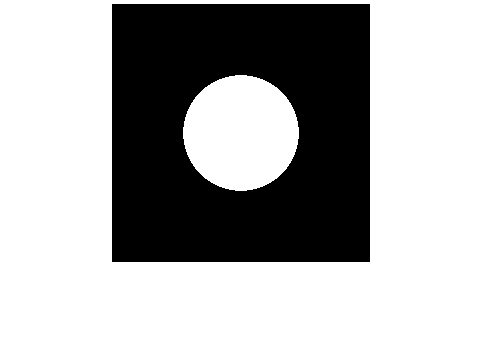

% the center mask: C
figure;
imshow(cenMask, [])

### The CE model 

The model postulates that the normalization is a constant


$$Z = \text{Const}$$


#### A example 

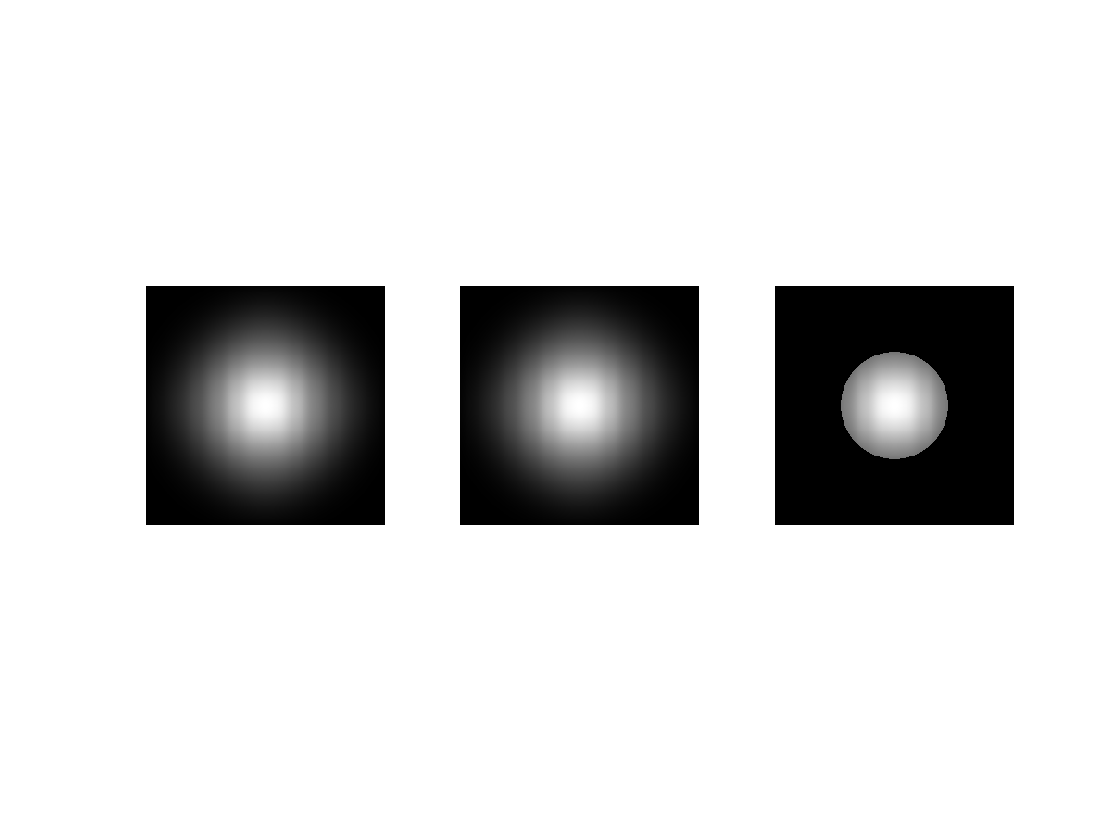

% example for CE model
params = [.1, 1];
sig = params(1); alpha = params(2);
const = 1-sig; theta_star = 1;
% energy: x, y, neuron orient, example, stim orient
E = surr_E(:, :, theta_star, :, 1);
% get normalizer: Z = const
Z = const;
% normalized energy: D(x,y,θ) = E(x,y,θ) ./ (sig + Z)
D = E ./ Z;
% sum over the response at center, and select the target orientation
% d = ∑_(x, y in C) D(x,y,θ*)
d = squeeze(mean(cenMask .* D(:, :, :, :, :), [1, 2]));
% add exponential
s = d.^alpha;
% sum over examples
r = squeeze(mean(s, [1]));

figure;
subplot(1, 3, 1)
imshow(squeeze(mean(E, 4)), [])
subplot(1, 3, 2)
imshow(squeeze(mean(D, 4)), [])
subplot(1, 3, 3)
imshow(squeeze(mean(cenMask.*D, 4)), [])

#### Get the curves

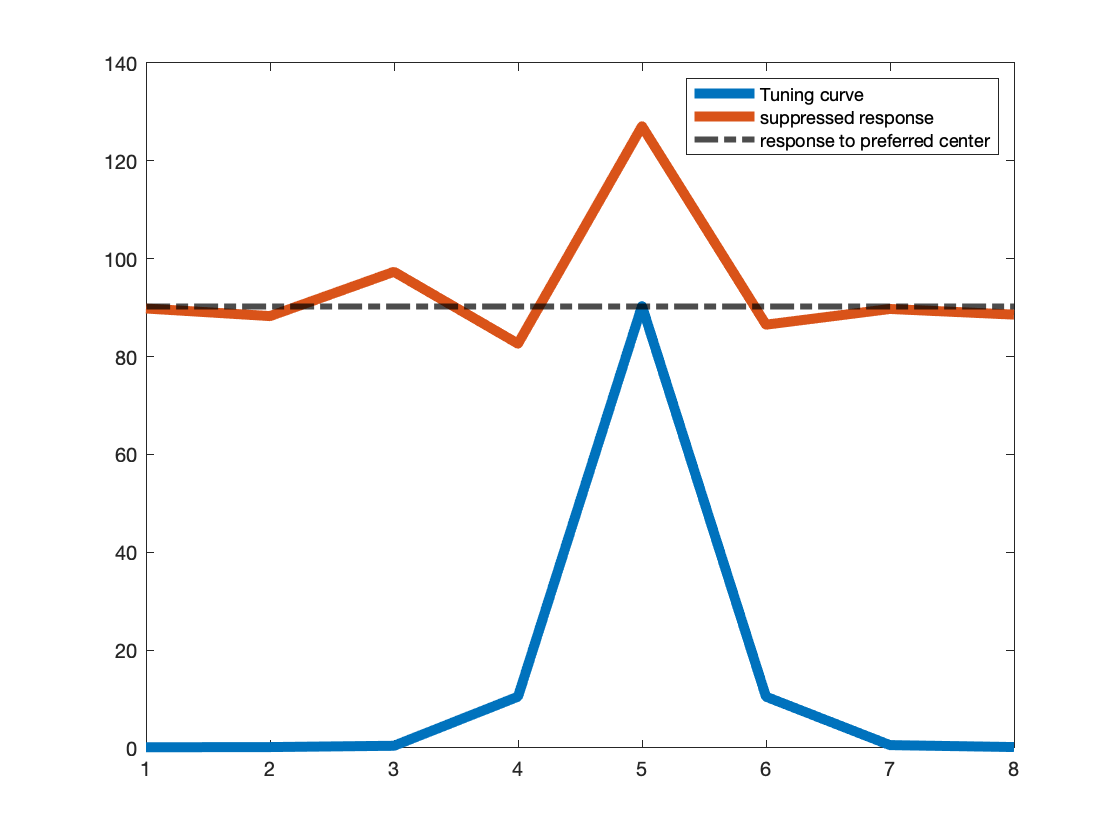

theta_star = 1; params = [.1, 1];
[tune_curve, prefer_res, supp_curve] =  getCurves(tune_E, surr_E, cenMask, 'CE', theta_star, params);

figure();
plot(tune_curve,'LineWidth', 5)
hold on
plot(supp_curve,'LineWidth', 5)
yline(prefer_res, '-.k', 'LineWidth', 3)
legend('Tuning curve', 'suppressed response', 'response to preferred center')

### The OTS model 

The model postulates that the normalization is a constant


$$Z(\theta) = \sum_{x',y',\theta'} E(x', y', \theta)F(x', y', \theta';\theta)$$


#### A example 

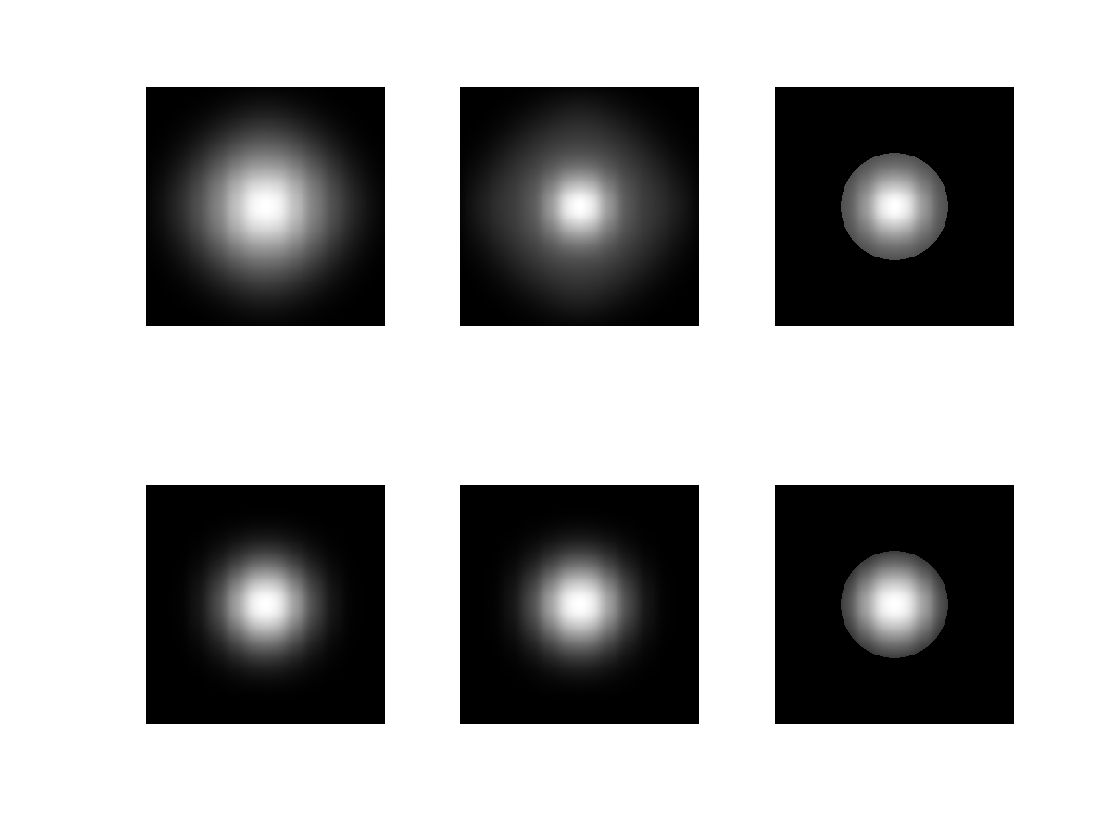

% example for the OTS model
params = [.1, 1];
sig = params(1); alpha = params(2);
const = 1-sig; theta_star = 1;
stim_idx = [1, 5];
figure;
for j = 1:2
    % energy: x, y, neuron orient, example, stim orient
    E = surr_E(:, :, :, :, stim_idx(j));
    % get normalizer: Z(θ) = ∑_{x,y,θ'}E(x,y,θ)F(x,y,θ';θ)
    sizeE = size(E);
    pMask = gen_disk(num, num*3/4, 1.2);
    sMask = gen_disk(num, num*3/4, .6);
    F = get_F(theta_star, pMask, sMask);
    Z = zeros(size(E));
    for theta_surr = 1:nOri
        Ftheta = squeeze(F(:, :, :, theta_surr));
        Z = Z + Ftheta.*E/nOri;
    end
    Z = mean(Z, [1, 2]);
    % normalized energy: D(x,y,θ) = E(x,y,θ) ./ (sig + Z)
    D = E ./ (sig + Z);
    D = D(:, :, theta_star, :, :);
    % sum over the response at center, and select the target orientation
    % d = ∑_(x, y in C) D(x,y,θ*)
    d = squeeze(mean(cenMask .* D, [1, 2]));
    % add exponential
    s = d.^alpha;
    % sum over examples
    r = squeeze(mean(s, [1]));
    
    % figure;
    % for i = 1:nOri
    %     subplot(2, 8, i)
    %     imshow(F(:, :, i), [])
    % end
    
    subplot(2, 3, (j-1)*3+1)
    imshow(squeeze(mean(E(:,:,theta_star,:), 4)), [])
    subplot(2, 3, (j-1)*3+2)
    imshow(squeeze(mean(D, 4)), [])
    subplot(2, 3, (j-1)*3+3)
    imshow(squeeze(mean(cenMask.*D, 4)), [])
end

#### Get the curves

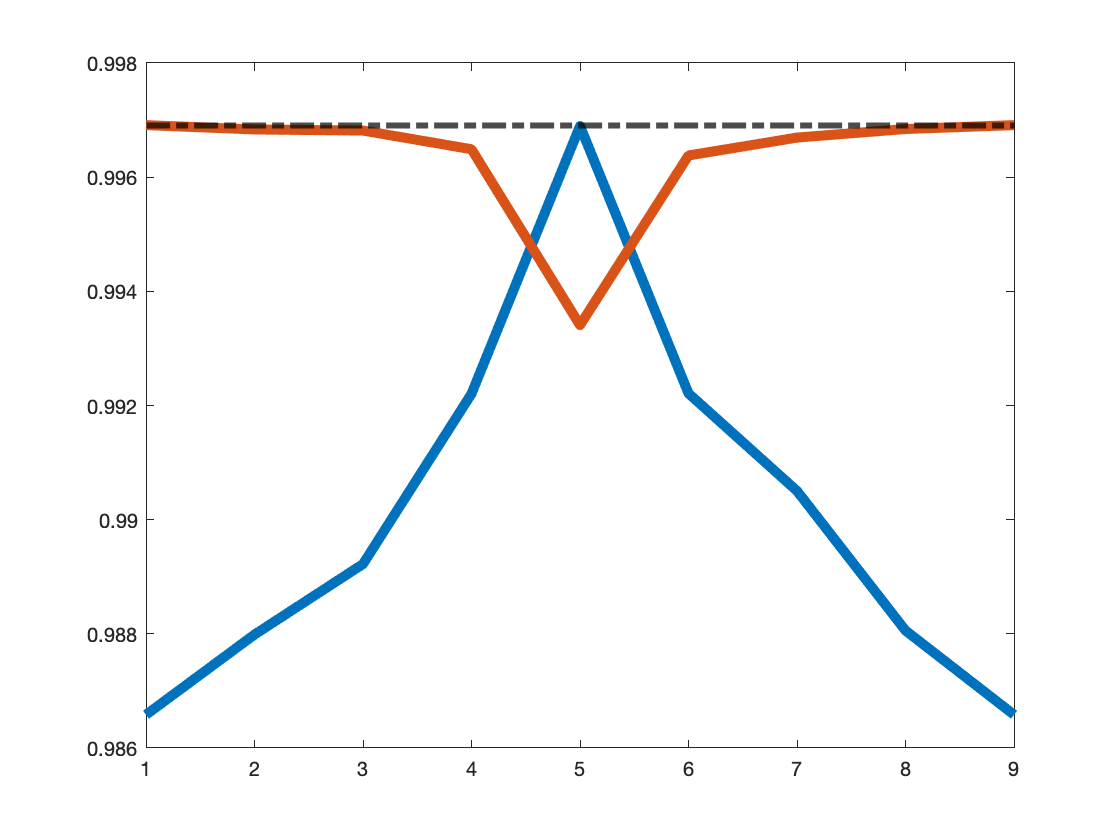

theta_star = 1; params = [.001, .1];
[tune_curve, prefer_res, supp_curve] =  getCurves(tune_E, surr_E, cenMask, 'OTS', theta_star, params);
tune_curve = [tune_curve, tune_curve(1)];
supp_curve = [supp_curve, supp_curve(1)];

figure();
plot(tune_curve,'LineWidth', 5)
hold on
plot(supp_curve,'LineWidth', 5)
yline(prefer_res, '-.k', 'LineWidth', 3)

#### A example 

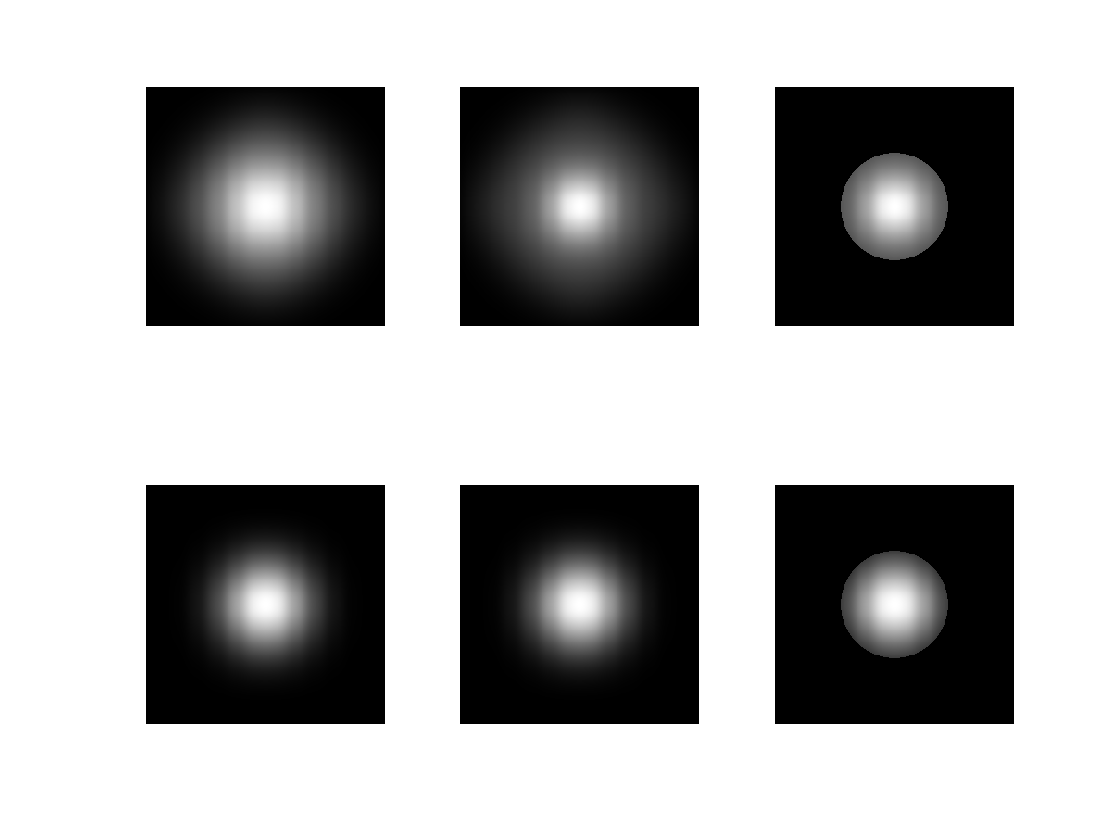

% example for the NOA model
params = [.1, 1];
sig = params(1); alpha = params(2);
const = 1-sig; theta_star = 1;
stim_idx = [1, 5];
figure;
for j = 1:2
    % energy: x, y, neuron orient, example, stim orient
    E = surr_E(:, :, :, :, stim_idx(j));
    % get normalizer: 
    % Eori(θ) = ∑_xy E(x,y,θ);
    % Z = std(Eori(θ))
    sizeE = size(E);
    E_ori = reshape(mean(E, [1, 2]), sizeE(3:4));
    Z = std(E_ori, 1);
    Z = reshape(Z, [1, 1, size(Z)]);
    % normalized energy: D(x,y,θ) = E(x,y,θ) ./ (sig + Z)
    D = E ./ (sig + Z);
    D = D(:, :, theta_star, :, :);
    % sum over the response at center, and select the target orientation
    % d = ∑_(x, y in C) D(x,y,θ*)
    d = squeeze(mean(cenMask .* D, [1, 2]));
    % add exponential
    s = d.^alpha;
    % sum over examples
    r = squeeze(mean(s, [1]));
    
    % figure;
    % for i = 1:nOri
    %     subplot(2, 8, i)
    %     imshow(F(:, :, i), [])
    % end
    
    subplot(2, 3, (j-1)*3+1)
    imshow(squeeze(mean(E(:,:,theta_star,:), 4)), [])
    subplot(2, 3, (j-1)*3+2)
    imshow(squeeze(mean(D, 4)), [])
    subplot(2, 3, (j-1)*3+3)
    imshow(squeeze(mean(cenMask.*D, 4)), [])
end

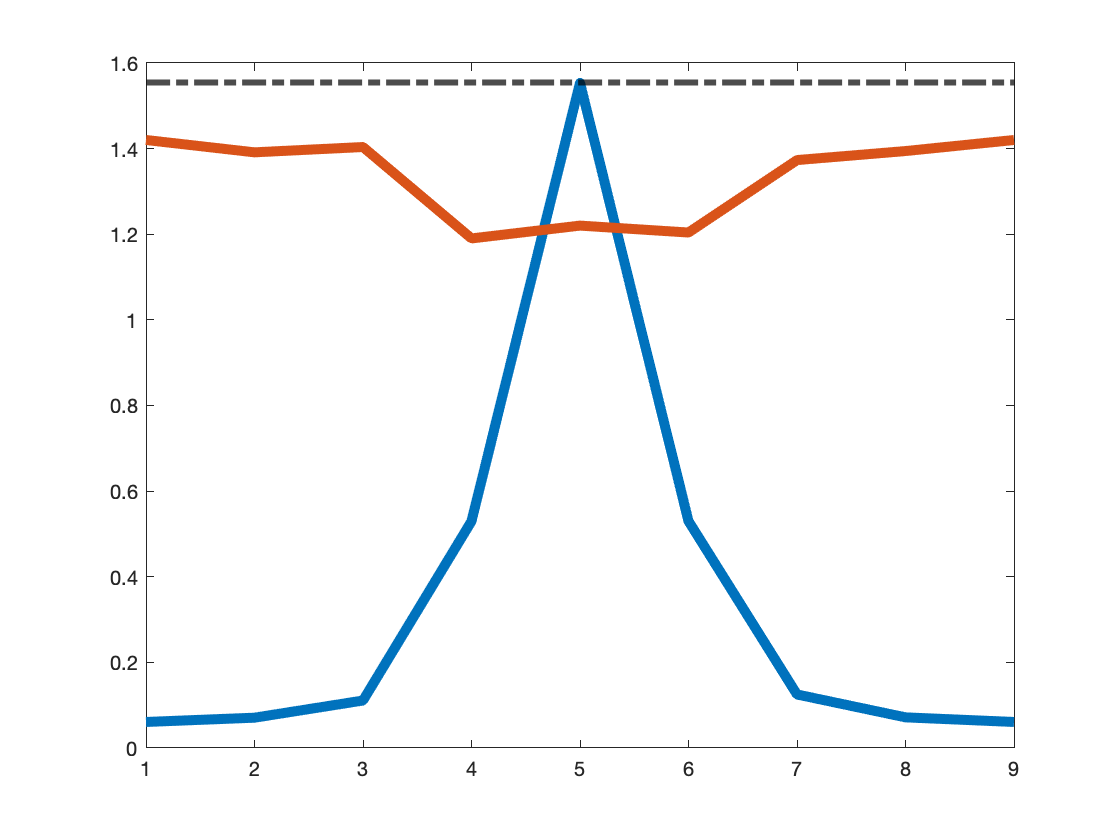

theta_star = 1; params = [.2, .5];
[tune_curve, prefer_res, supp_curve] =  getCurves(tune_E, surr_E, cenMask, 'NOA', theta_star, params);
tune_curve = [tune_curve, tune_curve(1)];
supp_curve = [supp_curve, supp_curve(1)];

figure();
plot(tune_curve,'LineWidth', 5)
hold on
plot(supp_curve,'LineWidth', 5)
yline(prefer_res, '-.k', 'LineWidth', 3)

function r = cal_d(E, mask, model, theta_star, params)

% dims: x, y, neuron orientation, example, stim orientation
sig = params(1); alpha = params(2);

% energy: x, y, neuron orient, example, stim orient

% get normalizer: Z
switch model
    case 'CE'
        % Z = const
        Z = 1 - sig;
        
    case 'OTS'
        numpix  = 400;
        fovs    = 12.5 * [1, 3/2, 1, 1]; % deg (the second data set had a larger field of view than the others)
        fov     = fovs(1);
        pixperdeg = numpix / fov;
        ppc     = round(pixperdeg./0.75); % pixels per cycle
        supp    = 6;
        
        num     = round(ppc * supp); % number of pixels in 2 cycles
        picMask = gen_disk(num, num*3/4, .9);
        cenMask = gen_disk(num, num*3/4, .6);
        nOri = 8;
        sizeE = size(E);
        F = get_F(theta_star, picMask, cenMask);
        Z = zeros(size(E));
        for theta_surr = 1:nOri
            Ftheta = squeeze(F(:, :, :, theta_surr));
            Z = Z + Ftheta.*E/nOri;
        end
        Z = mean(Z, [1, 2]);
        
    case 'NOA'
        % get normalizer: 
        % Eori(θ) = ∑_xy E(x,y,θ);
        % Z = std(Eori(θ))
        sizeE = size(E);
        E_ori = reshape(mean(E, [1, 2]), sizeE(3:5));
        Z = std(E_ori, 1);
        Z = reshape(Z, [1, 1, size(Z)]);
        
end

% normalized energy: D(x,y,θ) = E(x,y,θ) ./ (sig + Z)
D = E ./ (sig + Z);
% sum over the response at center, and select the target orientation
% d = ∑_(x, y in C) D(x,y,θ*)
d = squeeze(mean(mask .* D(:, :, theta_star, :, :), [1, 2]));
% add exponential
s = d.^alpha;
% sum over examples
r = squeeze(mean(s, [1]));

end

function [tune_curve, prefer_res, supp_curve] = getCurves(tune_E, surr_E, mask, model, theta_star, params)

% tuning curve
tune_curve = cal_d(tune_E, mask, model, theta_star, params);
temp = tune_curve;
tune_curve(1:4) = temp(5:8);
tune_curve(5:8) = temp(1:4);

% get the prefer response
prefer_res = tune_curve(5);

% get the suppression
surr_res = cal_d(surr_E, mask, model, theta_star, params);
temp = surr_res;
surr_curve(1:4) = temp(5:8);
surr_curve(5:8) = temp(1:4);
supp_curve = surr_curve;

end

function B = conv2d_mask(A, k, mask);
[r c] = size(A);
[m n] = size(k);
h = rot90(k, 2);
center = floor((size(h)+1)/2);
left = center(2) - 1;
right = n - center(2);
top = center(1) - 1;
bottom = m - center(1);
Rep = zeros(r + top + bottom, c + left + right);
for x = 1 + top : r + top
    for y = 1 + left : c + left
        Rep(x,y) = A(x - top, y - left);
    end
end
B = zeros(r , c);
for x = 1 : r
    for y = 1 : c
        if mask(x, y) == 1
            for i = 1 : m
                for j = 1 : n
                    q = x - 1;
                    w = y -1;
                    B(x, y) = B(x, y) + (Rep(i + q, j + w) * h(i, j));
                end
            end
        end
    end
end
end

function conEnergy = Icontrast_mask(stimulus, G_c, G_s, mask)

% contrast image size
sz = size(stimulus,1);
[nT, nF] = size(G_c);

% placeholders
conEnergy = nan(sz, sz, nT, nF);

% for all frequencies,
% in this project, there is only 1 frequency
for i = 1:nF
    % for all orientaitons
    for j = 1:nT
        
        % get the Gabor filters
        Gabor_c = G_c{j, i};
        Gabor_s = G_s{j, i};
        
        % compute the energy
        CE = conv2(stimulus,Gabor_c, mask).^2 ...
            + conv2(stimulus,Gabor_s, mask).^2;
        conEnergy(:, :, j, i) = CE;
    end
end

% combine the spatial frequencies
% E(x,y,θ) = 1/nF * ∑_f E(x,y,θ,f)
conEnergy = mean(conEnergy, 4);

end

function F = get_F(theta_star, picMask, cenMask)

sz = size(picMask);
F = nan([sz(1:2), 8, 8]);
for theta=1:8
    for theta_surr = 1:8
        if (theta == theta_star)&&(theta_surr == theta_star)
            F(:,:,theta, theta_surr) = picMask;
        else
            F(:,:,theta, theta_surr) = cenMask;
        end
    end
end

end
